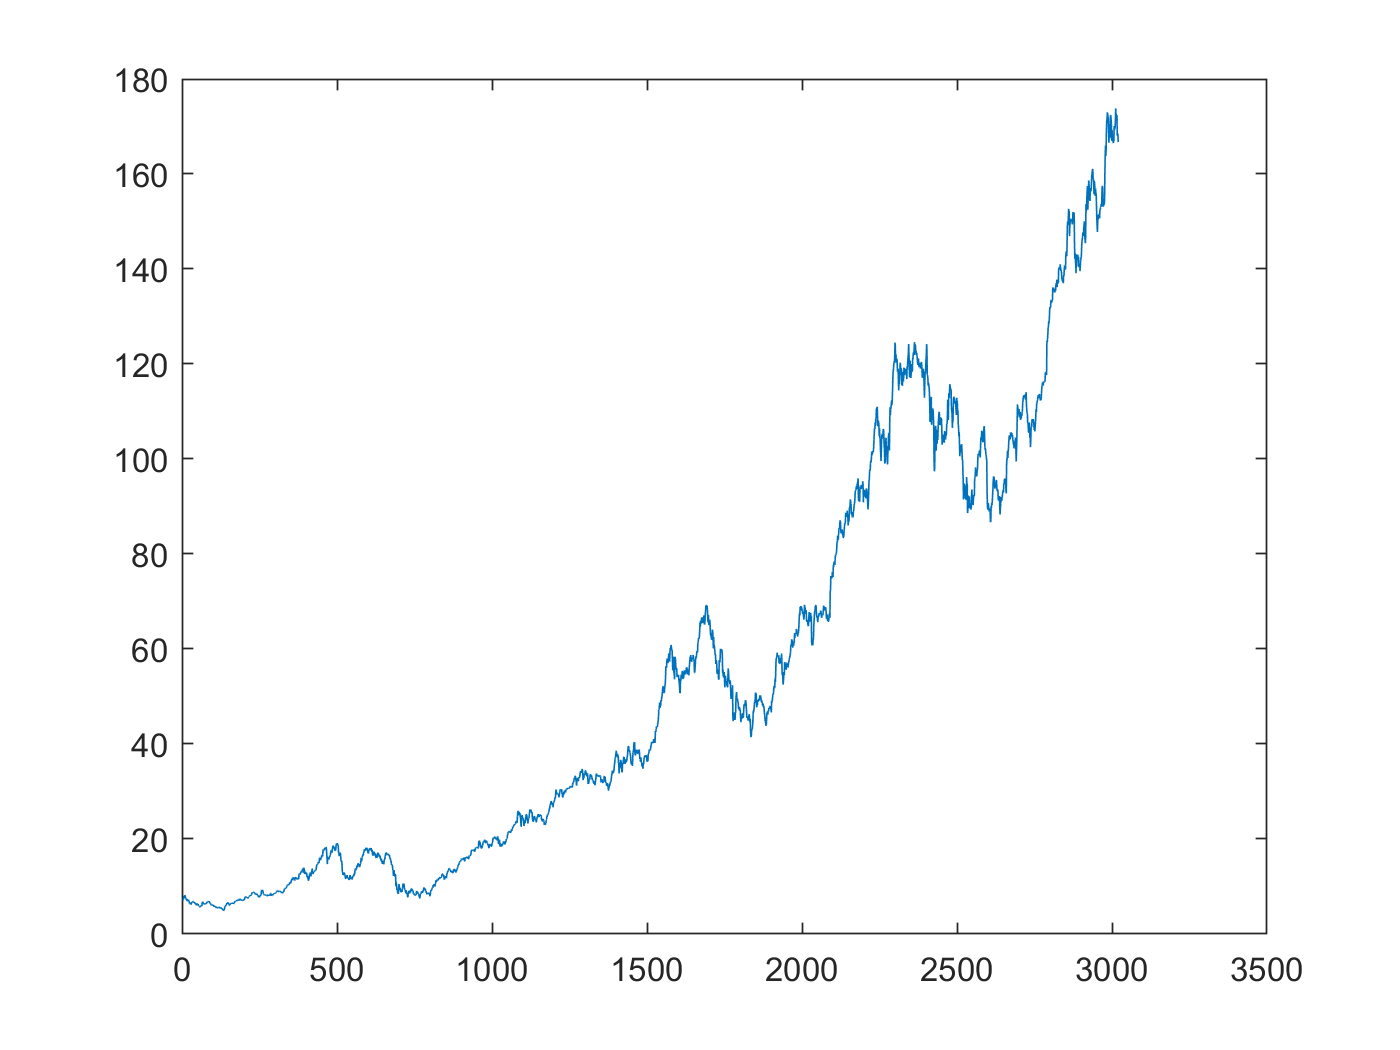

stock = get_yahoo_stockdata3('AAPL','01-Jan-2006', '01-Jan-2018');

% array with Adjusted closing price
adjClosePrice = stock.adjClosePrice;

% get dates for stock; already in correct order
dates = stock.DateTime;
actDates = datetime(dates, 'convertfrom', 'datenum');

% plot adjusted price --> x-axis is number and y-axis is price
plot(adjClosePrice);

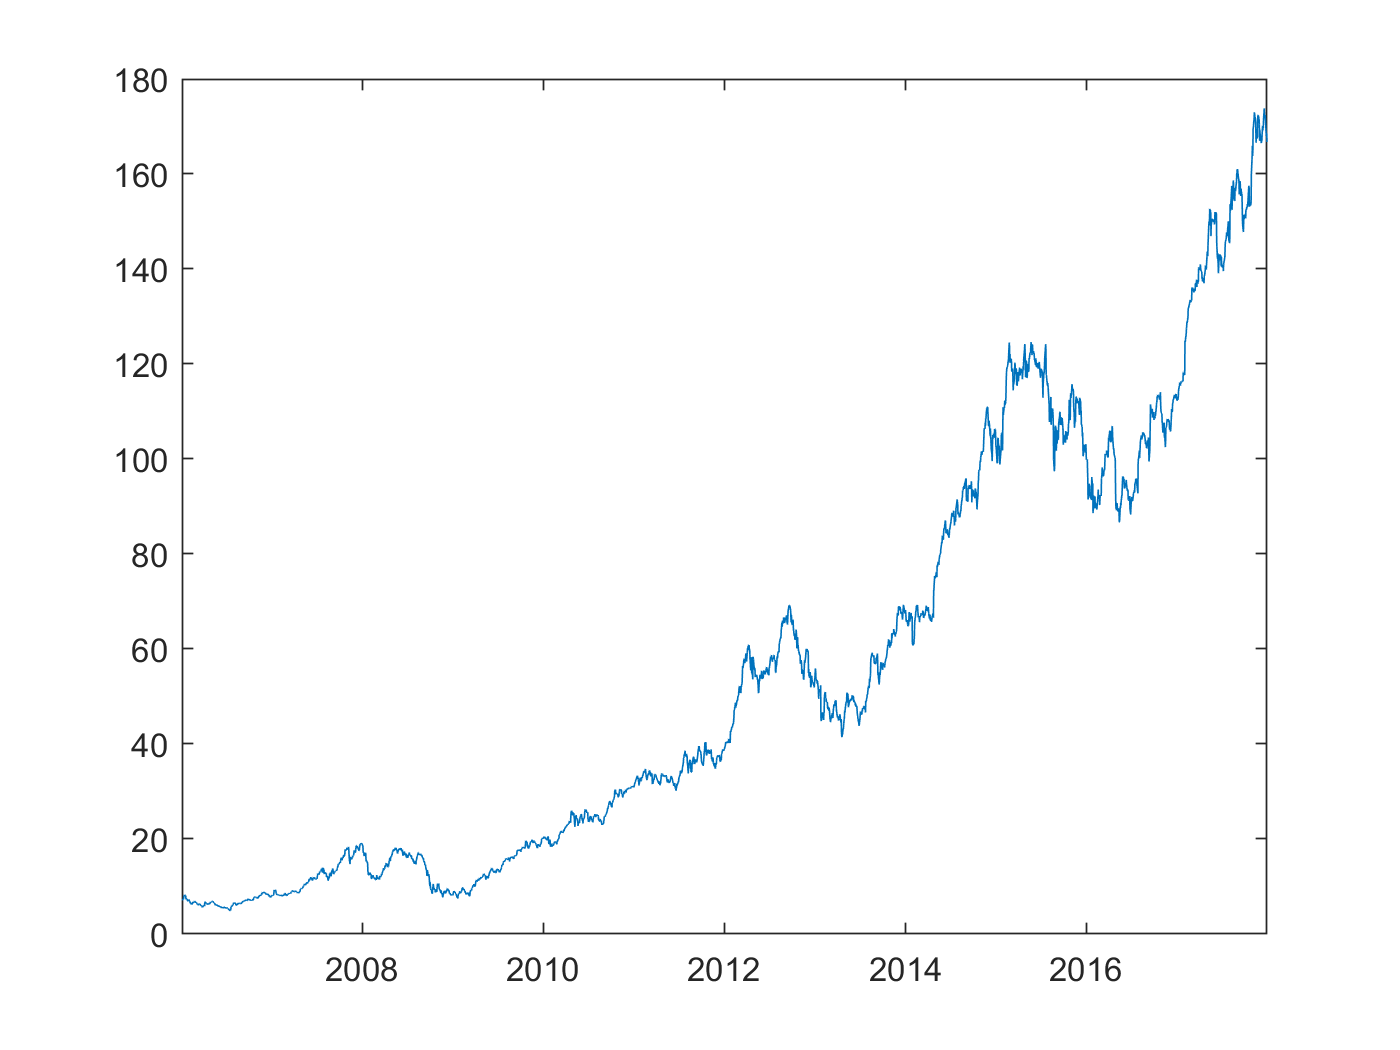


% plot adjusted price with correct dates
plot(actDates, adjClosePrice);

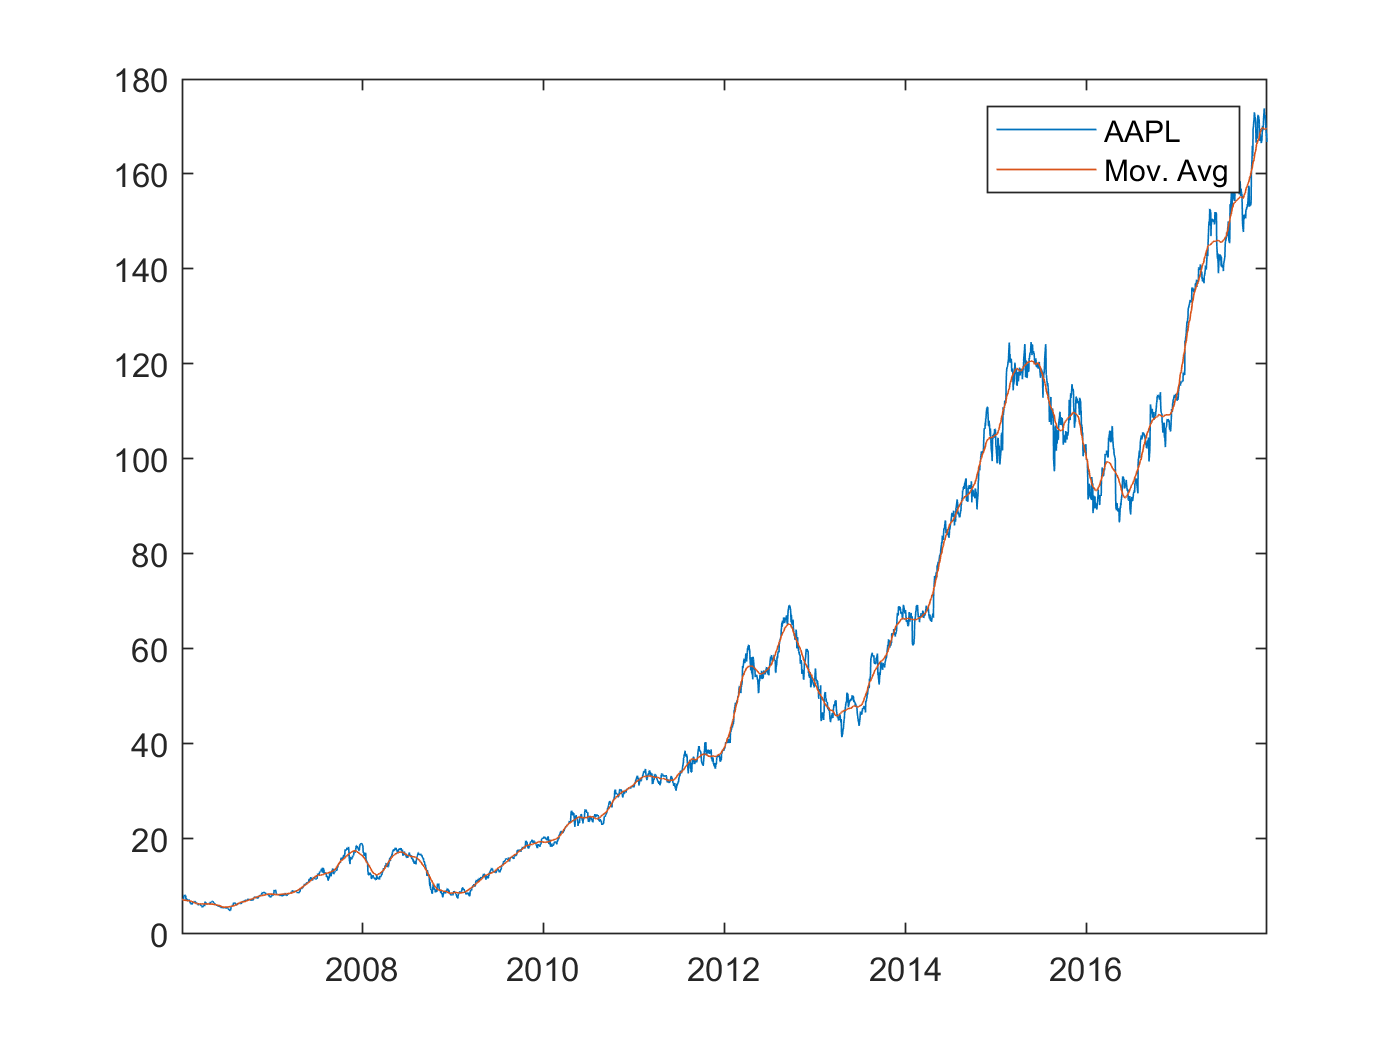


% calculate moving average for every 50 ticks, array has dimension of 1
movAvg50 = movmean(adjClosePrice, 50, 1);

% plot moving average on time
plot(actDates, adjClosePrice, actDates, movAvg50);
legend('AAPL', 'Mov. Avg');


% figuring out returns on stock
% log return or continuous returns --> it's a log return series
% histogram shows likelyhood of gain or loss in returns
returns = tick2ret(adjClosePrice, actDates, 'continuous');

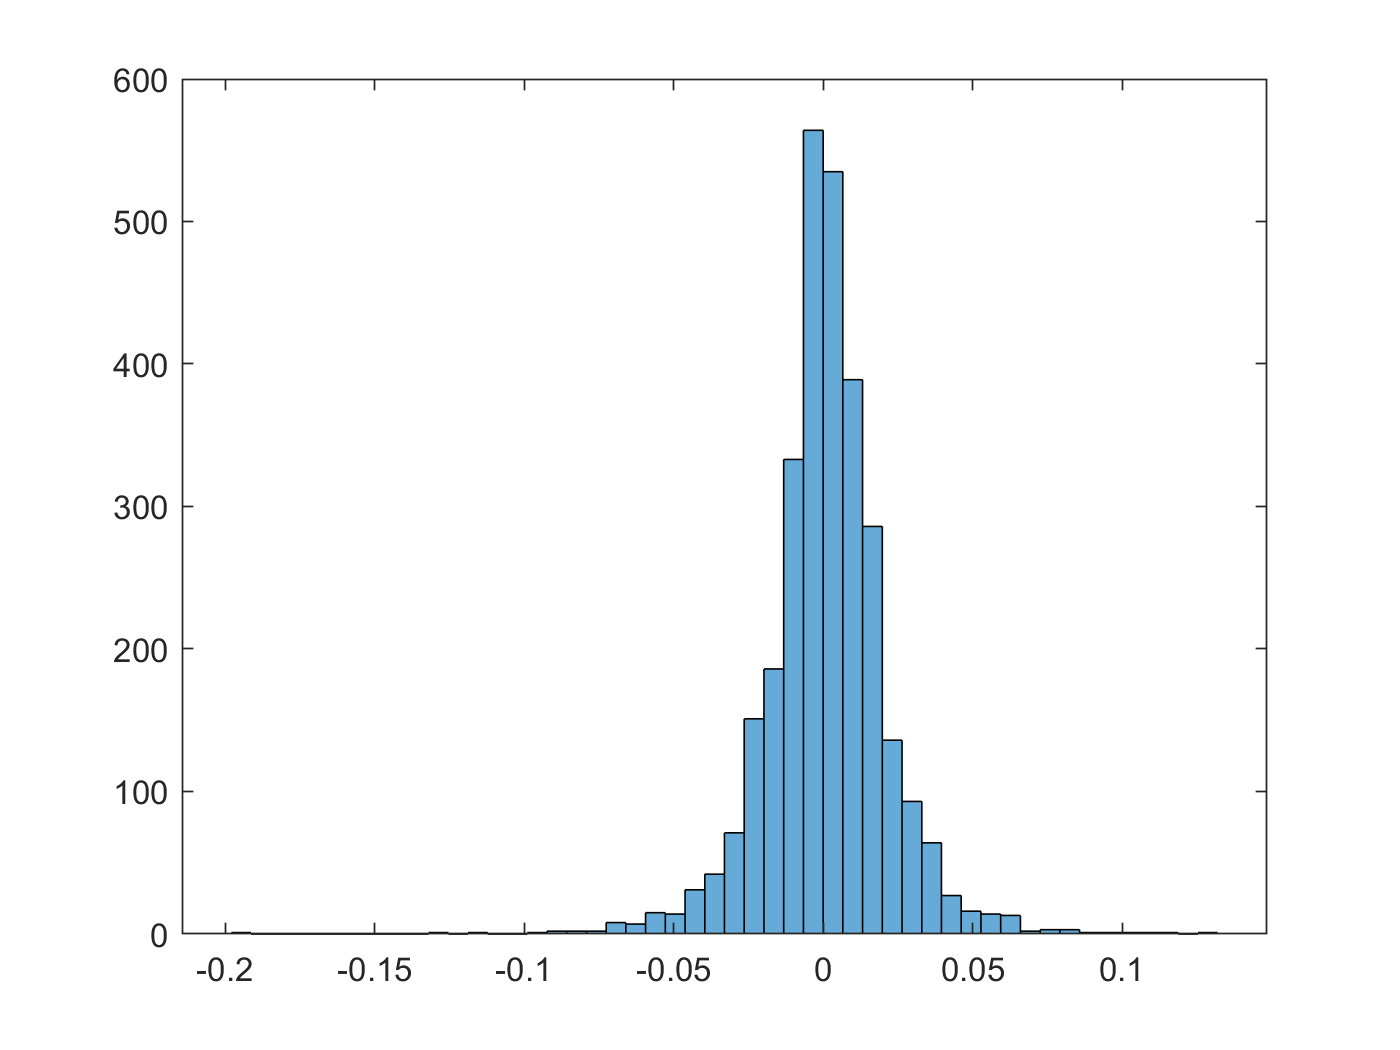

figure
histogram(returns, 50);


% using 252 because it's annualized; 252 trading days in an year
movAvg252 = tsmovavg(adjClosePrice, 's', 252, 1);

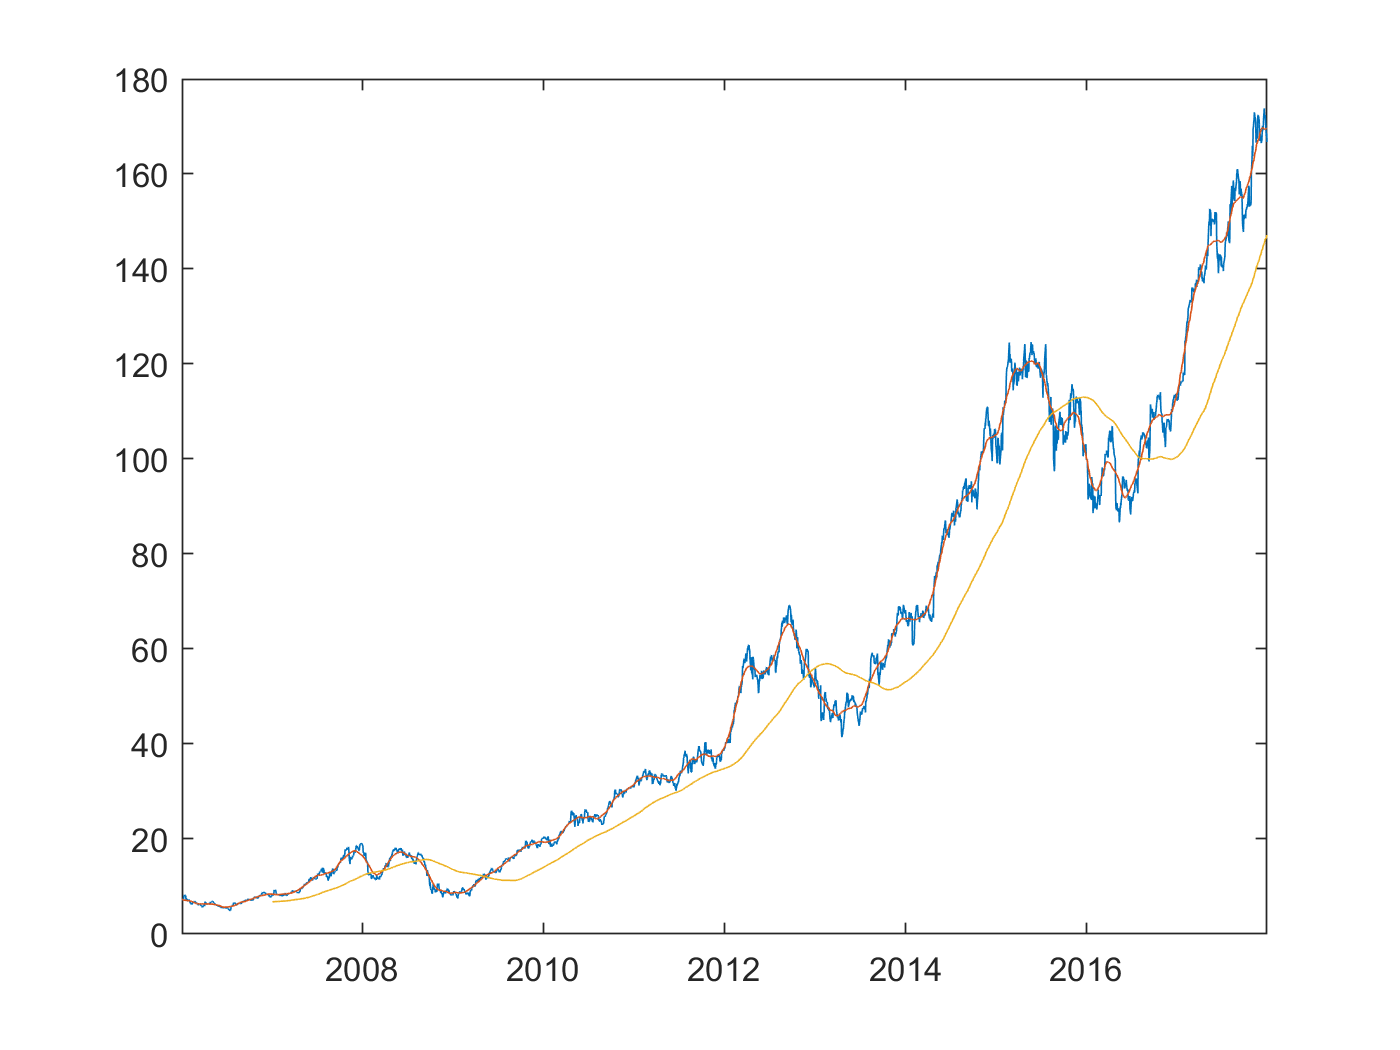

plot(actDates, adjClosePrice, actDates, movAvg50, actDates, movAvg252);

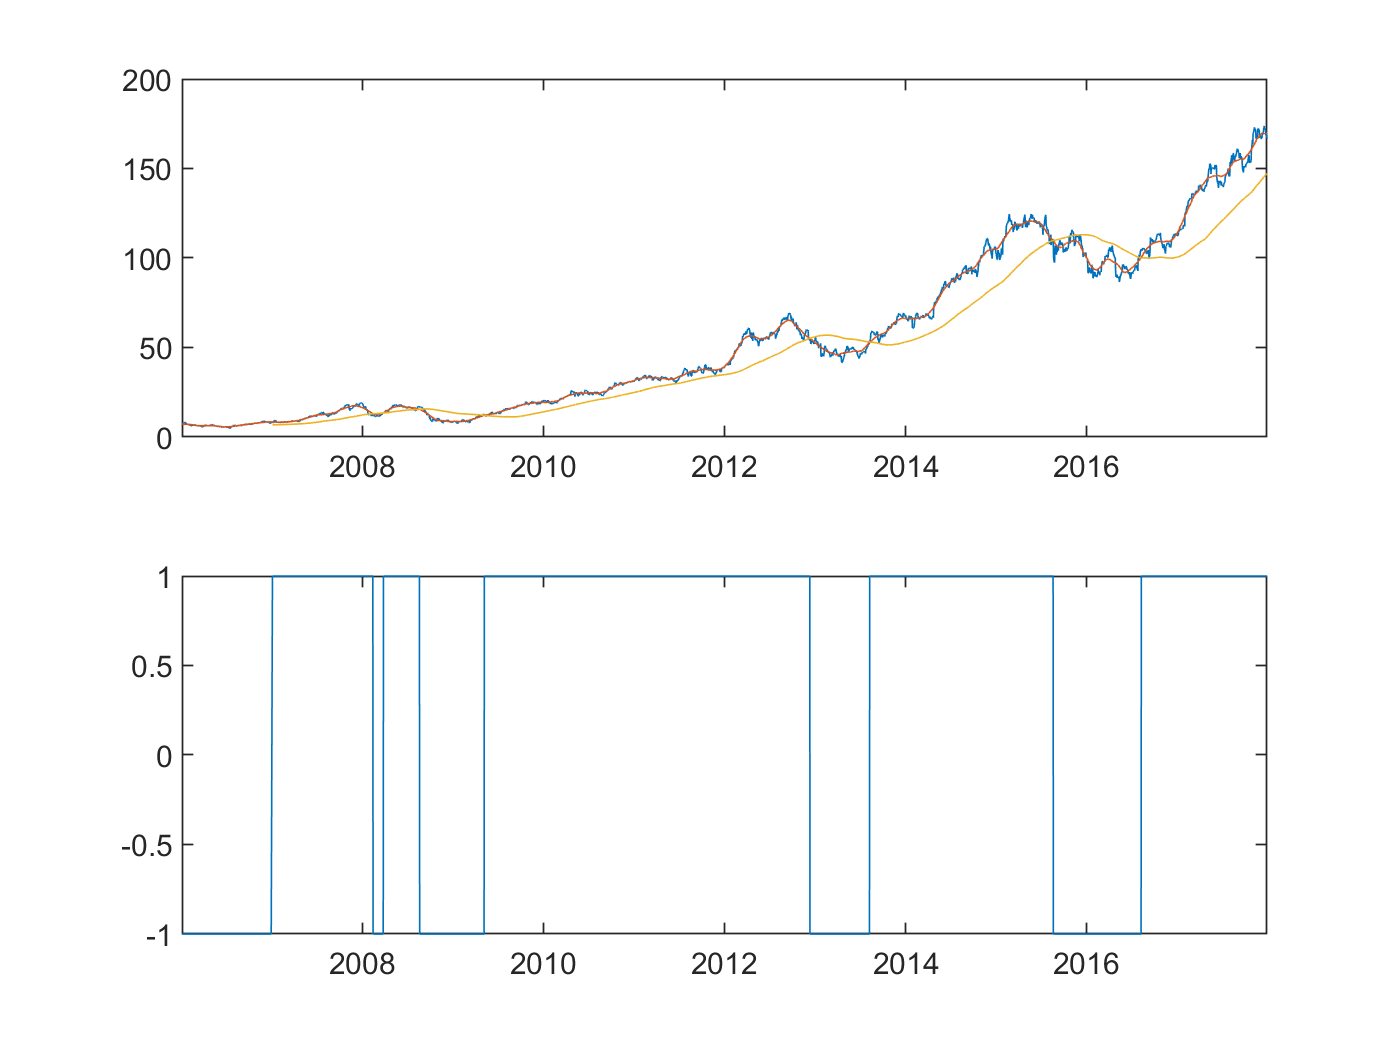


% one trading strategy consists of loking where the short-term moving average is above the long-term
% this figure will help decide when to sell or buy
% goes to 1 when short-term is above long-term (this is a buy-signal)
% goes to -1 when long-term is above short-terms (this is a sell-signal)
goodArea = (movAvg50 > movAvg252) * 2 - 1;
figure
subplot(2, 1, 1)
plot(actDates, adjClosePrice, actDates, movAvg50, actDates, movAvg252);
subplot(2, 1, 2)
plot(actDates, goodArea);



returns2 = tick2ret(adjClosePrice, actDates, 'continuous');

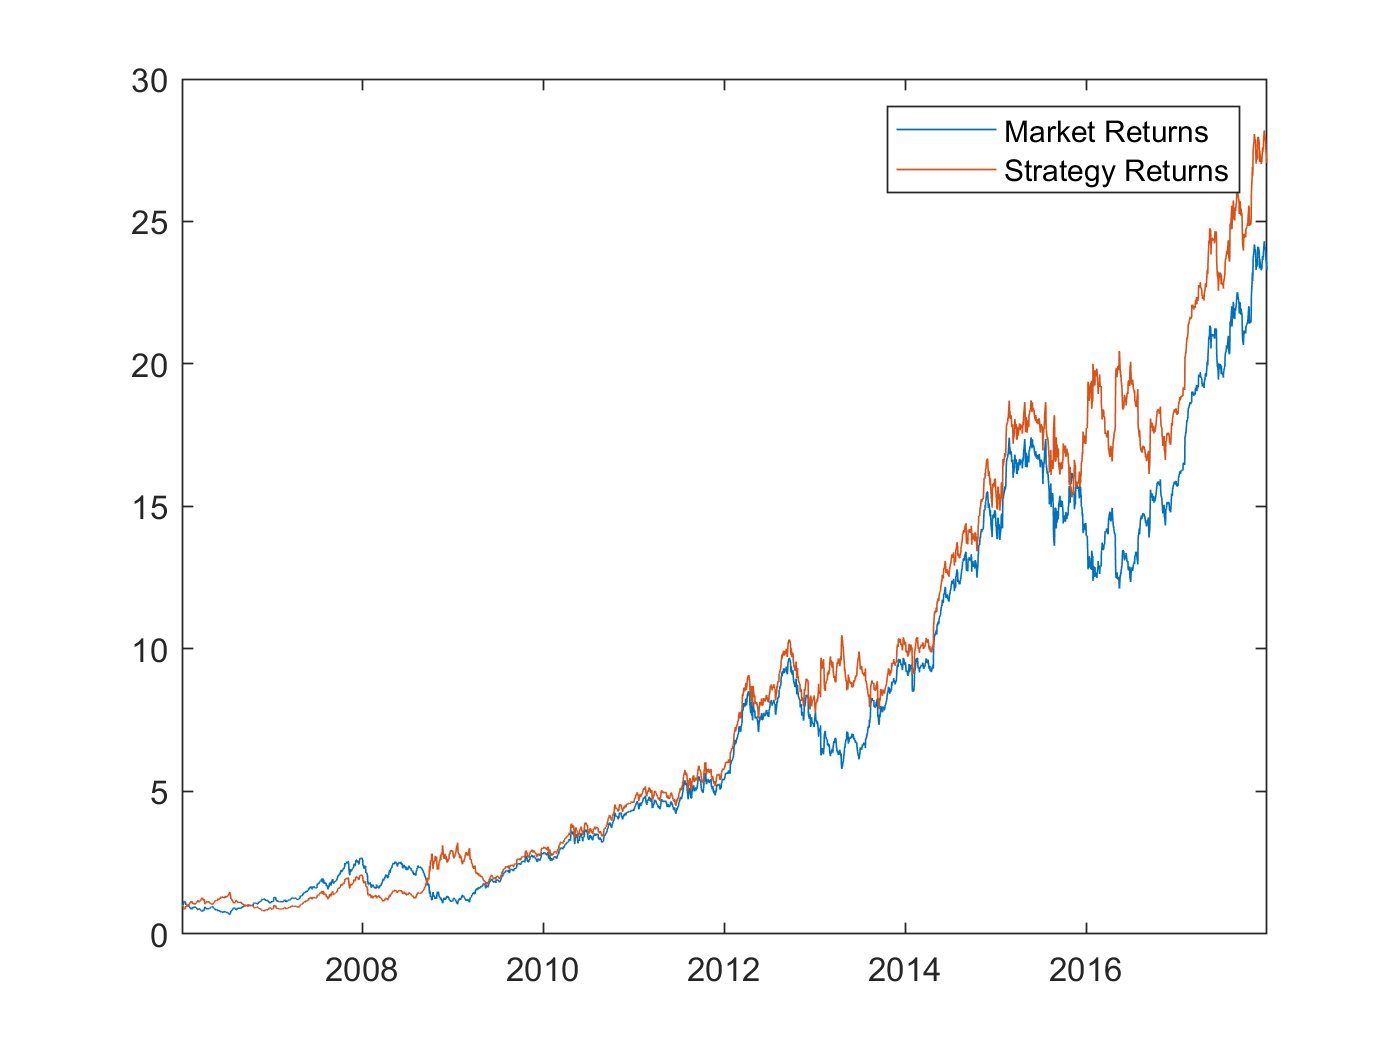

% strategy: multiplying all the 1s and -1s in the above goodArea vector by return at each time 
strategy = goodArea(2:end) .* returns2;
cumulativeMarket = exp(cumsum(returns2));
strategyOfReturns = exp(cumsum(strategy));
% plot between Market Returns and Specific Strategy Return
% difference between investing in market versus Specific Strategy
figure
plot(actDates(2:end), cumulativeMarket, actDates(2:end), strategyOfReturns);
legend('Market Returns', 'Strategy Returns');


% Annual Return and Voltaility of Two Different Methods
annualReturns = mean([returns2 strategy]) * 252;
annualVolatility = std([returns2 strategy]) * sqrt(252);
display(annualReturns);

annualReturns =     0.2629    0.2753


display(annualVolatility);

annualVolatility =     0.3255    0.3255


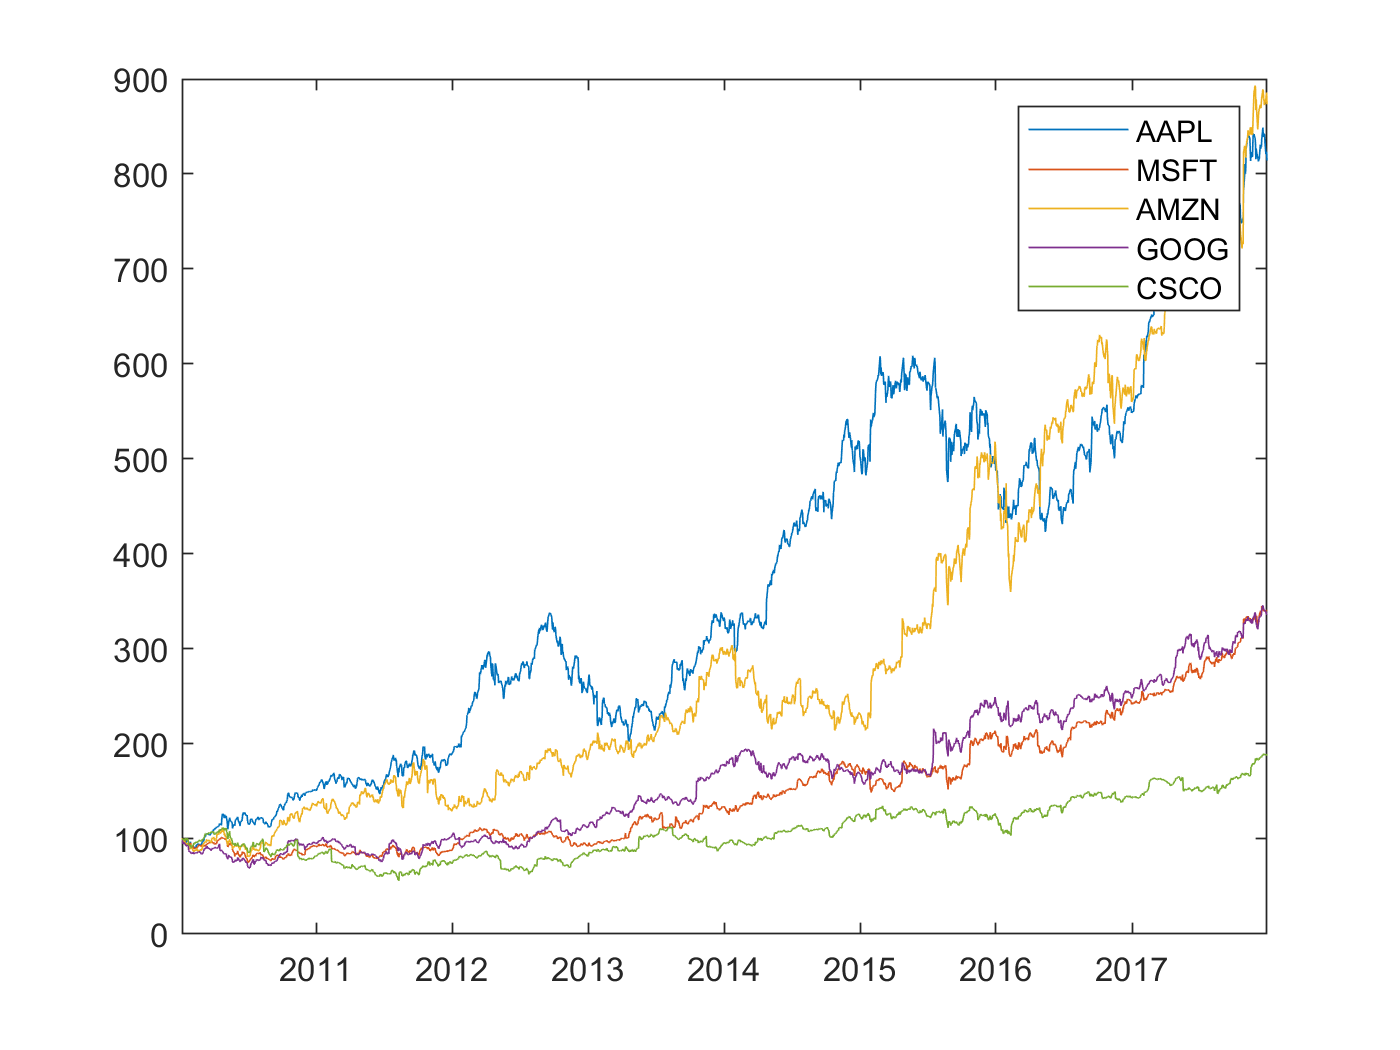


clear

comps = ['AAPL'; 'MSFT'; 'AMZN'; 'GOOG'];


% calculations and normalized price for first company 
info1 = get_yahoo_stockdata3(comps(1,:),'01-Jan-2010', '01-Jan-2018');
data1 = info1.adjClosePrice;
prices_norm1(:,1) = data1(:,1) / data1(1,1) * 100;

% calculations and normalized price for first company 
info2 = get_yahoo_stockdata3(comps(2,:),'01-Jan-2010', '01-Jan-2018');
data2 = info2.adjClosePrice;
prices_norm2(:,1) = data2(:,1) / data2(1,1) * 100;

% calculations and normalized price for first company 
info3 = get_yahoo_stockdata3(comps(3,:),'01-Jan-2010', '01-Jan-2018');
data3 = info3.adjClosePrice;
prices_norm3(:,1) = data3(:,1) / data3(1,1) * 100;

% calculations and normalized price for first company 
info4 = get_yahoo_stockdata3(comps(4,:),'01-Jan-2010', '01-Jan-2018');
data4 = info4.adjClosePrice;
prices_norm4(:,1) = data4(:,1) / data4(1,1) * 100;

% calculations and normalized price for first company 
info5 = get_yahoo_stockdata3('CSCO','01-Jan-2010', '01-Jan-2018');
data5 = info5.adjClosePrice;
prices_norm5(:,1) = data5(:,1) / data5(1,1) * 100;

time = datetime(info1.DateTime, 'convertfrom', 'datenum');

% Plotting time versus the normalized closing price for all companies
% Legend --> accounts for tickers that may be of different length
figure
plot(time, prices_norm1, time, prices_norm2, time, prices_norm3, time, prices_norm4, time, prices_norm5);
legend(comps(1,:), comps(2,:), comps(3,:), comps(4,:), 'CSCO');


%Or do it this way if all tackers have the same char length
% comps(end+1,:) = ['CSCO']'
% legend = (comps)

% logarithmic calculations of returns from Company 1
logReturn1 = tick2ret(data1, time, 'continuous');

returns1 = mean(logReturn1) * 252;

% logarithmic calculations of returns from Company 2
logReturn2 = tick2ret(data2, time, 'continuous');

returns2 = mean(logReturn2) * 252;

% logarithmic calculations of returns from Company 3
logReturn3 = tick2ret(data3, time, 'continuous');

returns3 = mean(logReturn3) * 252;

% logarithmic calculations of returns from Company 4
logReturn4 = tick2ret(data4, time, 'continuous');

returns4 = mean(logReturn4) * 252;

% logarithmic calculations of returns from Company 5
logReturn5 = tick2ret(data5, time, 'continuous');

returns5 = mean(logReturn5) * 252;

% display each of those returns
display([comps(1,:) ' = ' num2str(returns1)])

AAPL = 0.26267


display([comps(2,:) ' = ' num2str(returns2)])

MSFT = 0.15333


display([comps(3,:) ' = ' num2str(returns3)])

AMZN = 0.27144


display([comps(4,:) ' = ' num2str(returns4)])

GOOG = 0.15183


% different code for displaying comapnies that may have a different ticker length
display(['CSCO = ' num2str(returns5)])

CSCO = 0.078902



% calculation of total portfolio return
% logPortRets is a 5X5 matrix
% portRets is a 1X5 matrix
logPortRets = [logReturn1, logReturn2, logReturn3, logReturn4, logReturn5];
portRets = [returns1, returns2, returns3, returns4, returns5];

% weights are dependent on how much money you put into each company
% for now, we assume equal amount of money in each company
weights(1:length(portRets)) = 1./length(portRets);

% dot product of weights and returns will give total portfolio return
totPortRet = dot(portRets, weights);
display(totPortRet);

totPortRet = 0.1836


% finding volatility of this portfolio with the given weights
% covariance matrix from log returns
cMat = cov(logPortRets);

% portfolio variance calculation
% matric multiplication with vector; make a square matrix of weight
% then do two dot products
sqWeights = repmat(weights, length(portRets), 1);
variance = dot(weights , dot((cMat * 252), sqWeights));

% taking the square root of variance will give volatility or standard dev
volatility = sqrt(variance);
display(volatility);

volatility = 0.1853



% looping through different weights to see which has the best returns and volatility
trials = 1000;
poRets = zeros(trials, 1);
poVols = zeros(trials, 1);
highestRet = 0;
highestVol = 0;
highestRetW = 0;
highestVolW = 0;
for i = 1:trials
    % random weights but need get them to add to 1
    w = rand(1, length(portRets));
    w = w ./ sum(w);
    sqW = repmat(w, length(portRets), 1);
    poRets(i) = dot(w, portRets);
    poVols(i) = sqrt(dot(w, dot(cMat*252, sqW)));
    if poRets(i) > highestRet
        highestRet = poRets(i);
        highestRetW = w;
    end
    if poVols(i) > highestVol
        highestVol = poVols(i);
        highestVolW = w;
    end
end

display(['Highest Return: ' num2str(highestRet)]);

Highest Return: 0.24293


display('Weights for Highest Return');

Weights for Highest Return


display(highestRetW);

highestRetW =     0.0750    0.0280    0.6961    0.1940    0.0070


display(['Highest Volatility: ' num2str(highestVol)]);

Highest Volatility: 0.33438


display('Weights for Highest Volatility');

Weights for Highest Volatility


display(highestVolW);

highestVolW =     0.0750    0.0280    0.6961    0.1940    0.0070


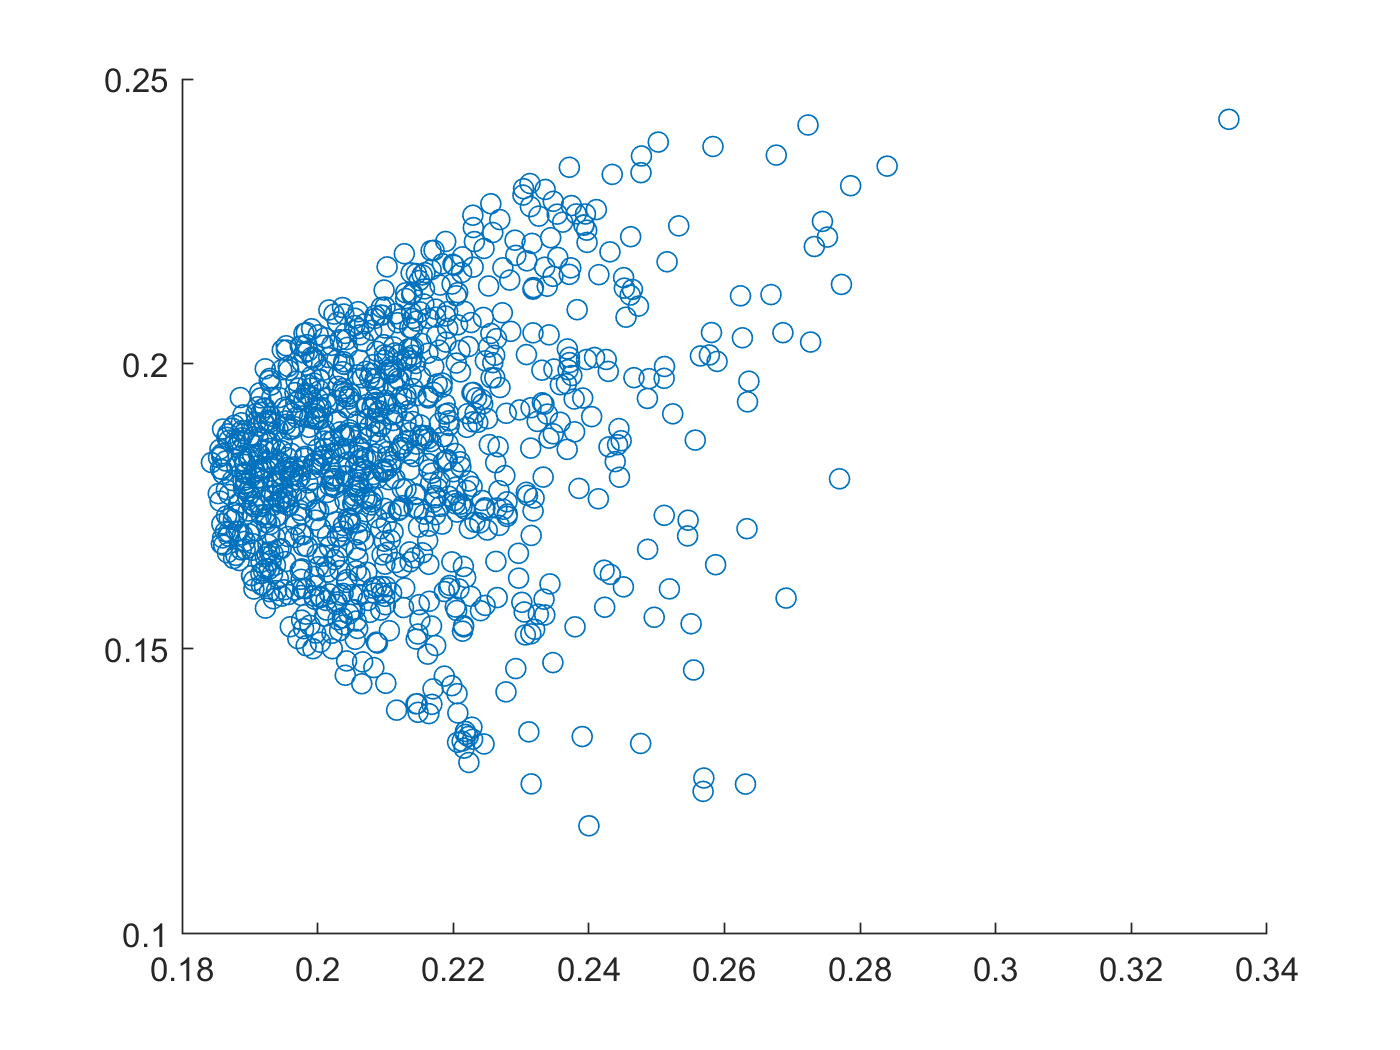



% scatter plot of volatility versus returns
figure
scatter(poVols, poRets);